zipFile = 'Cranfield_Collection.zip';
folder = 'CranfieldCollection';
unzip(zipFile, folder);
disp(['Files extracted to ', folder]);

Files extracted to CranfieldCollection


path = 'CranfieldCollection';
dataStorage = fileDatastore(path, ...
                   'ReadFcn', @fileread, ...
                   'FileExtensions', '.txt', ...
                   'IncludeSubfolders', true);
docs = dataStorage.readall();
docs = string(docs);
disp(docs(1:20));

    "experiment investig aerodynam wing slipstream experiment studi wing propel slipstream made order determin spanwis distribut lift increas due slipstream differ angl attack wing differ free stream slipstream veloc ratio result intend part evalu basi differ theoret treatment problem compar span load curv togeth support evid show substanti part lift increment produc slipstream due destal boundari layer control effect integr remain lift increment subtract destal lift found agre well potenti flow theori empir evalu destal effect made specif configur experi"
    "simpl shear flow past flat plate incompress fluid small viscos studi high speed viscou flow past two dimension bodi usual necessari consid curv shock wave emit nose lead edg bodi consequ exist inviscid rotat flow region shock wave boundari layer situat aris instanc studi hyperson viscou flow past flat plate situat somewhat differ prandtl classic boundari layer problem prandtl origin problem inviscid free stream outsid boundari l

cleanDocs = preprocessText(docs);
function preprocessedText = preprocessText(docs)
    tokenizedD = tokenizedDocument(docs);
    tokenizedD = lower(tokenizedD);
    tokenizedD = removeStopWords(tokenizedD);
    tokenizedD = erasePunctuation(tokenizedD);
    tokenizedD = normalizeWords(tokenizedD, 'Style', 'stem');
    preprocessedText = tokenizedD;
end
disp(cleanDocs(1:20)); 

  20×1 tokenizedDocument:

     79 tokens: experi investig aerodynam wing slipstream experi studi wing propel slipstream made order determin spanwi distribut lift increa due slipstream differ angl attack wing differ free stream slipstream veloc ratio result intend part evalu basi differ theoret treatment problem compar span load curv togeth support evid show substanti part lift increment produc slipstream due destal boundari layer control effect integr remain lift increment subtract destal lift found agr well potenti flow theori empir evalu destal effect made specif configur experi
    115 tokens: simpl shear flow past flat plate incompress fluid small visco studi high speed viscou flow past two dimens bodi usual necessari consid curv shock wave emit nose lead edg bodi consequ exist inviscid rotat flow region shock wave boundari layer situat ari instanc studi hyperson viscou flow past flat plate situat somewha

bow = bagOfWords(cleanDocs);
disp(bow);

  bagOfWords with properties:

          Counts: [4200×4340 double]
      Vocabulary: ["experi"    "investig"    "aerodynam"    "wing"    "slipstream"    "studi"    "propel"    "made"    "order"    "determin"    "spanwi"    "distribut"    "lift"    "increa"    "due"    "differ"    "angl"    …    ] (1×4340 string)
        NumWords: 4340
    NumDocuments: 4200



topWords = topkwords(bow, 10);
disp('Top 10 Words:');

Top 10 Words:


disp(topWords);

       Word       Count
    __________    _____

    "flow"        6237 
    "pressur"     4146 
    "number"      4041 
    "boundari"    3555 
    "layer"       3402 
    "result"      3261 
    "effect"      2994 
    "method"      2661 
    "theori"      2646 
    "solut"       2547 



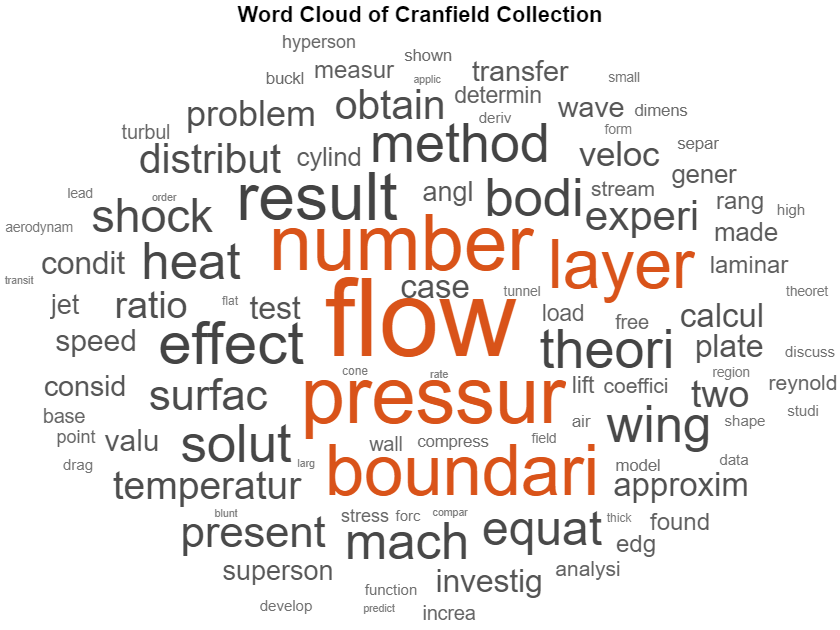

figure;
wordcloud(bow);
title('Word Cloud of Cranfield Collection');

save('BoW_Cranfield.mat', 'bow');
load('BoW_Cranfield.mat', 'bow');
query = [
    "one-dimensional transient heat flow in a multilayer slab .", ...
    "measurements of the effect of two-dimensional and three-dimensional roughness elements on boundary layer transition .", ...
    "the flow field in the diffuser of a radial compressor .", ...
    "generalised-newtonian theory .", ...
    "what design factors can be used to control lift-drag ratios at mach numbers above 5 ."
];
processedQ = preprocessQ(query);
function preprocessedQ = preprocessQ(query)
    preprocessedQ = cell(1, length(query));
    for i = 1:length(query)
        tokenizedQ = tokenizedDocument(query(i));
        tokenizedQ = lower(tokenizedQ);
        tokenizedQ = removeStopWords(tokenizedQ);
        tokenizedQ = erasePunctuation(tokenizedQ);
        tokenizedQ = normalizeWords(tokenizedQ, 'Style', 'stem');
        preprocessedQ{i} = tokenizedQ;
    end
end
disp(processedQ(1:5));

    {[6 tokens: onedimension transient heat flow multilay slab]}    {[9 tokens: measur effect twodimension threedimension rough element boundari layer transit]}    {[5 tokens: flow field diffus radial compressor]}    {[2 tokens: generalisednewtonian theori]}    {[8 tokens: design factor control liftdrag ratio mach number 5]}



encodedQ = cell(length(processedQ), 1);
for i = 1:length(processedQ)
    encodedQ{i} = encode(bow, processedQ{i});
end
disp('Encoded query:');

Encoded query:


disp(encodedQ);

    {[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

docMatrix = bow.Counts; 
numQ = length(encodedQ);
numD = size(docMatrix, 1);
cosineSimilarities = zeros(numQ, numD);
for q = 1:numQ
    vectorQ = encodedQ{q}; 
    for d = 1:numD
        vectorD = docMatrix(d, :); 
        cosineSimilarities(q, d) = dot(vectorQ, vectorD) / ...
                                   (norm(vectorQ) * norm(vectorD));
    end
end
disp('Cosine Similarities (Query vs docs):');

Cosine Similarities (Query vs docs):


disp(cosineSimilarities);

  Columns 1 through 3276

    0.0412    0.1796    0.2085    0.1646    0.5893    0.4069    0.0840         0    0.0690         0         0    0.0435    0.1995         0         0    0.0432    0.1661    0.2601    0.1414    0.0326    0.2100    0.1698    0.2927    0.0962    0.1273    0.1302    0.1254    0.1929    0.1971    0.0958         0         0    0.1682    0.1949    0.0836    0.1493    0.2526    0.1104    0.1604         0         0         0         0    0.0845    0.3442         0         0    0.1684    0.2003    0.1508    0.2336    0.0354    0.0439    0.0614    0.1571    0.0267    0.0665    0.0664    0.1314    0.0398    0.1521    0.1128    0.1254    0.0267         0    0.0890         0    0.0451    0.0398    0.0463    0.0516    0.0412    0.1054    0.1780         0         0    0.1241         0         0         0    0.2282    0.1088         0    0.2828    0.1319    0.1272    0.1066    0.2098    0.1518    0.1493    0.3382         0    0.0620    0.1714    0.1375    0.0431    0.3218    

docRanks = zeros(numQ, numD);
for q = 1:numQ
    [~, sortedIndices] = sort(cosineSimilarities(q, :), 'descend');
    docRanks(q, :) = sortedIndices; 
end
disp('Document Rankings:');

Document Rankings:


disp(docRanks);

  Columns 1 through 2730

           5        1405        2805         395        1795        3195         485        1885        3285           6        1406        2806         872        2272        3672         332        1732        3132         775        2175        3575         579        1979        3379         398        1798        3198         873        2273        3673          45        1445        2845         144        1544        2944          91        1491        2891         550        1950        3350         404        1804        3204         582        1982        3382         651        2051        3451          97        1497        2897         500        1900        3300         706        2106        3506         158        1558        2958         310        1710        3110        1222        2622        4022        1245        2645        4045         660        2060        3460          23        1423        2823         303        1703        3103  

for q = 1:numQ
    fprintf('Query %d: %s\n', q, query(q));
    fprintf('Top 20 docs:\n');
    topDocs = docRanks(q, 1:20);
    for i = 1:20
        docIndex = topDocs(i);
        fprintf('Document %d (Cosine Similarity: %.4f)\n', docIndex, cosineSimilarities(q, docIndex));
    end
    disp('------------------------');
end

Query 1: one-dimensional transient heat flow in a multilayer slab .


Top 20 docs:


Document 5 (Cosine Similarity: 0.5893)
Document 1405 (Cosine Similarity: 0.5893)
Document 2805 (Cosine Similarity: 0.5893)
Document 395 (Cosine Similarity: 0.4507)
Document 1795 (Cosine Similarity: 0.4507)
Document 3195 (Cosine Similarity: 0.4507)
Document 485 (Cosine Similarity: 0.4110)
Document 1885 (Cosine Similarity: 0.4110)
Document 3285 (Cosine Similarity: 0.4110)
Document 6 (Cosine Similarity: 0.4069)
Document 1406 (Cosine Similarity: 0.4069)
Document 2806 (Cosine Similarity: 0.4069)
Document 872 (Cosine Similarity: 0.3734)
Document 2272 (Cosine Similarity: 0.3734)
Document 3672 (Cosine Similarity: 0.3734)
Document 332 (Cosine Similarity: 0.3618)
Document 1732 (Cosine Similarity: 0.3618)
Document 3132 (Cosine Similarity: 0.3618)
Document 775 (Cosine Similarity: 0.3522)
Document 2175 (Cosine Similarity: 0.3522)


------------------------


Query 2: measurements of the effect of two-dimensional and three-dimensional roughness elements on boundary layer transition .


Top 20 docs:


Document 8 (Cosine Similarity: 0.6706)
Document 1408 (Cosine Similarity: 0.6706)
Document 2808 (Cosine Similarity: 0.6706)
Document 96 (Cosine Similarity: 0.6024)
Document 1496 (Cosine Similarity: 0.6024)
Document 2896 (Cosine Similarity: 0.6024)
Document 7 (Cosine Similarity: 0.5714)
Document 1407 (Cosine Similarity: 0.5714)
Document 2807 (Cosine Similarity: 0.5714)
Document 43 (Cosine Similarity: 0.5574)
Document 1443 (Cosine Similarity: 0.5574)
Document 2843 (Cosine Similarity: 0.5574)
Document 1211 (Cosine Similarity: 0.5075)
Document 2611 (Cosine Similarity: 0.5075)
Document 4011 (Cosine Similarity: 0.5075)
Document 80 (Cosine Similarity: 0.4857)
Document 1480 (Cosine Similarity: 0.4857)
Document 2880 (Cosine Similarity: 0.4857)
Document 671 (Cosine Similarity: 0.4830)
Document 2071 (Cosine Similarity: 0.4830)


------------------------


Query 3: the flow field in the diffuser of a radial compressor .


Top 20 docs:


Document 18 (Cosine Similarity: 0.5203)
Document 1418 (Cosine Similarity: 0.5203)
Document 2818 (Cosine Similarity: 0.5203)
Document 775 (Cosine Similarity: 0.4842)
Document 2175 (Cosine Similarity: 0.4842)
Document 3575 (Cosine Similarity: 0.4842)
Document 216 (Cosine Similarity: 0.4061)
Document 1616 (Cosine Similarity: 0.4061)
Document 3016 (Cosine Similarity: 0.4061)
Document 1222 (Cosine Similarity: 0.4047)
Document 2622 (Cosine Similarity: 0.4047)
Document 4022 (Cosine Similarity: 0.4047)
Document 1273 (Cosine Similarity: 0.3953)
Document 2673 (Cosine Similarity: 0.3953)
Document 4073 (Cosine Similarity: 0.3953)
Document 579 (Cosine Similarity: 0.3833)
Document 1979 (Cosine Similarity: 0.3833)
Document 3379 (Cosine Similarity: 0.3833)
Document 653 (Cosine Similarity: 0.3650)
Document 2053 (Cosine Similarity: 0.3650)


------------------------


Query 4: generalised-newtonian theory .


Top 20 docs:


Document 820 (Cosine Similarity: 0.6468)
Document 2220 (Cosine Similarity: 0.6468)
Document 3620 (Cosine Similarity: 0.6468)
Document 593 (Cosine Similarity: 0.5120)
Document 1993 (Cosine Similarity: 0.5120)
Document 3393 (Cosine Similarity: 0.5120)
Document 232 (Cosine Similarity: 0.5026)
Document 1632 (Cosine Similarity: 0.5026)
Document 3032 (Cosine Similarity: 0.5026)
Document 27 (Cosine Similarity: 0.5017)
Document 1427 (Cosine Similarity: 0.5017)
Document 2827 (Cosine Similarity: 0.5017)
Document 195 (Cosine Similarity: 0.4730)
Document 1595 (Cosine Similarity: 0.4730)
Document 2995 (Cosine Similarity: 0.4730)
Document 951 (Cosine Similarity: 0.4472)
Document 2351 (Cosine Similarity: 0.4472)
Document 3751 (Cosine Similarity: 0.4472)
Document 1048 (Cosine Similarity: 0.4423)
Document 2448 (Cosine Similarity: 0.4423)


------------------------


Query 5: what design factors can be used to control lift-drag ratios at mach numbers above 5 .


Top 20 docs:


Document 1341 (Cosine Similarity: 0.4208)
Document 2741 (Cosine Similarity: 0.4208)
Document 4141 (Cosine Similarity: 0.4208)
Document 1188 (Cosine Similarity: 0.4206)
Document 2588 (Cosine Similarity: 0.4206)
Document 3988 (Cosine Similarity: 0.4206)
Document 1381 (Cosine Similarity: 0.3853)
Document 2781 (Cosine Similarity: 0.3853)
Document 4181 (Cosine Similarity: 0.3853)
Document 971 (Cosine Similarity: 0.3829)
Document 2371 (Cosine Similarity: 0.3829)
Document 3771 (Cosine Similarity: 0.3829)
Document 748 (Cosine Similarity: 0.3713)
Document 2148 (Cosine Similarity: 0.3713)
Document 3548 (Cosine Similarity: 0.3713)
Document 689 (Cosine Similarity: 0.3702)
Document 2089 (Cosine Similarity: 0.3702)
Document 3489 (Cosine Similarity: 0.3702)
Document 1338 (Cosine Similarity: 0.3668)
Document 2738 (Cosine Similarity: 0.3668)


------------------------


tfidfWeights = tfidf(bow);
disp('TF-IDF Weights Matrix:');

TF-IDF Weights Matrix:


disp(tfidfWeights);

   (1,1)       3.6769
   (7,1)       1.2256
  (11,1)       1.2256
  (12,1)       1.2256
  (15,1)       1.2256
  (16,1)       1.2256
  (17,1)       2.4513
  (19,1)       1.2256
  (25,1)       2.4513
  (29,1)       1.2256
  (30,1)       4.9025
  (35,1)       1.2256
  (37,1)       1.2256
  (39,1)       1.2256
  (40,1)       1.2256
  (41,1)       3.6769
  (42,1)       1.2256
  (43,1)       1.2256
  (47,1)       1.2256
  (52,1)       2.4513
  (53,1)       1.2256
  (58,1)       1.2256
  (69,1)       1.2256
  (70,1)       1.2256
  (74,1)       1.2256
  (78,1)       2.4513
  (84,1)       2.4513
  (99,1)       2.4513
 (101,1)       1.2256
 (103,1)       2.4513
 (109,1)       2.4513
 (112,1)       1.2256
 (115,1)       1.2256
 (121,1)       1.2256
 (123,1)       3.6769
 (131,1)       1.2256
 (137,1)       1.2256
 (139,1)       1.2256
 (140,1)       1.2256
 (142,1)       1.2256
 (154,1)       1.2256
 (156,1)       1.2256
 (165,1)       1.2256
 (167,1)       1.2256
 (168,1)       1.2256
 (170,1)  

save('TFIDF_Weights.mat', 'tfidfWeights');
encodedQtfidf = cell(length(processedQ), 1);
for i = 1:length(processedQ)
    encodedQtfidf{i} = encode(bow, processedQ{i}); 
    encodedQtfidf{i} = encodedQtfidf{i} .* log(size(tfidfWeights, 1) ./ sum(tfidfWeights > 0));
end
disp('Encoded query with TF-IDF Weights:');

Encoded query with TF-IDF Weights:


disp(encodedQtfidf);

    {[               0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.6526 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 3.6889 1.5305 0 0 4.6052 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0

tfidfCosSim = zeros(numQ, numD);
for q = 1:numQ
    vectorQ = encodedQtfidf{q}; 
    for d = 1:numD
        vectorD = tfidfWeights(d, :); 
        tfidfCosSim(q, d) = dot(vectorQ, vectorD) / ...
                            (norm(vectorQ) * norm(vectorD));
    end
end
disp('TF-IDF Cosine Similarities (Query vs docs):');

TF-IDF Cosine Similarities (Query vs docs):


disp(tfidfCosSim);

  Columns 1 through 3276

    0.0018    0.0115    0.0178    0.0131    0.6572    0.3425    0.0036         0    0.0043         0         0    0.0110    0.0605         0         0    0.0022    0.0085    0.0111    0.0087    0.0095    0.0474    0.0179    0.0442    0.0232    0.0075    0.0076    0.0080    0.0190    0.2130    0.0849         0         0    0.0074    0.0090    0.0045    0.0298    0.0439    0.0062    0.0092         0         0         0         0    0.0173    0.0539         0         0    0.0100    0.0531    0.0293    0.0918    0.0020    0.0029    0.0127    0.0468    0.0016    0.0036    0.0038    0.0080    0.0019    0.0266    0.0312    0.0071    0.0014         0    0.0259         0    0.0128    0.0021    0.0026    0.0162    0.0092    0.0127    0.0247         0         0    0.0300         0         0         0    0.0408    0.0382         0    0.0259    0.0165    0.0063    0.0050    0.0177    0.0109    0.3111    0.4306         0    0.0032    0.0208    0.0996    0.0019    0.0213    

tfidfDocRanks = zeros(numQ, numD);
for q = 1:numQ
    [~, sortedIndices] = sort(tfidfCosSim(q, :), 'descend');
    tfidfDocRanks(q, :) = sortedIndices; 
end
disp('TF-IDF Document Rankings:');

TF-IDF Document Rankings:


disp(tfidfDocRanks);

  Columns 1 through 2730

           5        1405        2805         485        1885        3285          91        1491        2891         582        1982        3382           6        1406        2806          90        1490        2890        1028        2428        3828         144        1544        2944         395        1795        3195         399        1799        3199          29        1429        2829         869        2269        3669         706        2106        3506         978        2378        3778         981        2381        3781         980        2380        3780         579        1979        3379         159        1559        2959         546        1946        3346         542        1942        3342         873        2273        3673        1330        2730        4130         860        2260        3660         349        1749        3149         707        2107        3507          95        1495        2895         158        1558        2958  

for q = 1:numQ
    fprintf('Query %d: %s\n', q, query(q));
    fprintf('Top 20 docs (TF-IDF Cosine Similarity):\n');
    topDocsTFIDF = tfidfDocRanks(q, 1:20);
    for i = 1:20
        docIndex = topDocsTFIDF(i);
        fprintf('Document %d (Cosine Similarity: %.4f)\n', docIndex, tfidfCosSim(q, docIndex));
    end
    disp('------------------------');
end

Query 1: one-dimensional transient heat flow in a multilayer slab .


Top 20 docs (TF-IDF Cosine Similarity):


Document 5 (Cosine Similarity: 0.6572)
Document 1405 (Cosine Similarity: 0.6572)
Document 2805 (Cosine Similarity: 0.6572)
Document 485 (Cosine Similarity: 0.4370)
Document 1885 (Cosine Similarity: 0.4370)
Document 3285 (Cosine Similarity: 0.4370)
Document 91 (Cosine Similarity: 0.4306)
Document 1491 (Cosine Similarity: 0.4306)
Document 2891 (Cosine Similarity: 0.4306)
Document 582 (Cosine Similarity: 0.4181)
Document 1982 (Cosine Similarity: 0.4181)
Document 3382 (Cosine Similarity: 0.4181)
Document 6 (Cosine Similarity: 0.3425)
Document 1406 (Cosine Similarity: 0.3425)
Document 2806 (Cosine Similarity: 0.3425)
Document 90 (Cosine Similarity: 0.3111)
Document 1490 (Cosine Similarity: 0.3111)
Document 2890 (Cosine Similarity: 0.3111)
Document 1028 (Cosine Similarity: 0.2395)
Document 2428 (Cosine Similarity: 0.2395)


------------------------


Query 2: measurements of the effect of two-dimensional and three-dimensional roughness elements on boundary layer transition .


Top 20 docs (TF-IDF Cosine Similarity):


Document 8 (Cosine Similarity: 0.7884)
Document 1408 (Cosine Similarity: 0.7884)
Document 2808 (Cosine Similarity: 0.7884)
Document 96 (Cosine Similarity: 0.7862)
Document 1496 (Cosine Similarity: 0.7862)
Document 2896 (Cosine Similarity: 0.7862)
Document 7 (Cosine Similarity: 0.5647)
Document 1407 (Cosine Similarity: 0.5647)
Document 2807 (Cosine Similarity: 0.5647)
Document 43 (Cosine Similarity: 0.5556)
Document 1443 (Cosine Similarity: 0.5556)
Document 2843 (Cosine Similarity: 0.5556)
Document 710 (Cosine Similarity: 0.5511)
Document 2110 (Cosine Similarity: 0.5511)
Document 3510 (Cosine Similarity: 0.5511)
Document 80 (Cosine Similarity: 0.5433)
Document 1480 (Cosine Similarity: 0.5433)
Document 2880 (Cosine Similarity: 0.5433)
Document 40 (Cosine Similarity: 0.4564)
Document 1440 (Cosine Similarity: 0.4564)


------------------------


Query 3: the flow field in the diffuser of a radial compressor .


Top 20 docs (TF-IDF Cosine Similarity):


Document 216 (Cosine Similarity: 0.4557)
Document 1616 (Cosine Similarity: 0.4557)
Document 3016 (Cosine Similarity: 0.4557)
Document 589 (Cosine Similarity: 0.4315)
Document 1989 (Cosine Similarity: 0.4315)
Document 3389 (Cosine Similarity: 0.4315)
Document 591 (Cosine Similarity: 0.3811)
Document 1991 (Cosine Similarity: 0.3811)
Document 3391 (Cosine Similarity: 0.3811)
Document 237 (Cosine Similarity: 0.3805)
Document 1637 (Cosine Similarity: 0.3805)
Document 3037 (Cosine Similarity: 0.3805)
Document 543 (Cosine Similarity: 0.3657)
Document 1943 (Cosine Similarity: 0.3657)
Document 3343 (Cosine Similarity: 0.3657)
Document 138 (Cosine Similarity: 0.3443)
Document 1538 (Cosine Similarity: 0.3443)
Document 2938 (Cosine Similarity: 0.3443)
Document 18 (Cosine Similarity: 0.3298)
Document 1418 (Cosine Similarity: 0.3298)


------------------------


Query 4: generalised-newtonian theory .


Top 20 docs (TF-IDF Cosine Similarity):


Document 820 (Cosine Similarity: 0.2769)
Document 2220 (Cosine Similarity: 0.2769)
Document 3620 (Cosine Similarity: 0.2769)
Document 232 (Cosine Similarity: 0.2615)
Document 1632 (Cosine Similarity: 0.2615)
Document 3032 (Cosine Similarity: 0.2615)
Document 593 (Cosine Similarity: 0.2610)
Document 1993 (Cosine Similarity: 0.2610)
Document 3393 (Cosine Similarity: 0.2610)
Document 27 (Cosine Similarity: 0.2594)
Document 1427 (Cosine Similarity: 0.2594)
Document 2827 (Cosine Similarity: 0.2594)
Document 195 (Cosine Similarity: 0.2065)
Document 1595 (Cosine Similarity: 0.2065)
Document 2995 (Cosine Similarity: 0.2065)
Document 1075 (Cosine Similarity: 0.1989)
Document 2475 (Cosine Similarity: 0.1989)
Document 3875 (Cosine Similarity: 0.1989)
Document 752 (Cosine Similarity: 0.1960)
Document 2152 (Cosine Similarity: 0.1960)


------------------------


Query 5: what design factors can be used to control lift-drag ratios at mach numbers above 5 .


Top 20 docs (TF-IDF Cosine Similarity):


Document 368 (Cosine Similarity: 0.3423)
Document 1768 (Cosine Similarity: 0.3423)
Document 3168 (Cosine Similarity: 0.3423)
Document 748 (Cosine Similarity: 0.3286)
Document 2148 (Cosine Similarity: 0.3286)
Document 3548 (Cosine Similarity: 0.3286)
Document 638 (Cosine Similarity: 0.2514)
Document 2038 (Cosine Similarity: 0.2514)
Document 3438 (Cosine Similarity: 0.2514)
Document 1349 (Cosine Similarity: 0.2136)
Document 2749 (Cosine Similarity: 0.2136)
Document 4149 (Cosine Similarity: 0.2136)
Document 1380 (Cosine Similarity: 0.2085)
Document 2780 (Cosine Similarity: 0.2085)
Document 4180 (Cosine Similarity: 0.2085)
Document 834 (Cosine Similarity: 0.1936)
Document 2234 (Cosine Similarity: 0.1936)
Document 3634 (Cosine Similarity: 0.1936)
Document 969 (Cosine Similarity: 0.1878)
Document 2369 (Cosine Similarity: 0.1878)


------------------------


fileName = 'Query-Doc.xlsx'; 
try
    [num, txt, raw] = xlsread(fileName);
    disp('Excel file loaded successfully.');
catch
    disp('Error loading the Excel file');
    return;
end

Excel file loaded successfully.


excelInfo = sheetnames(fileName); 
disp('Sheets in the Excel file:');

Sheets in the Excel file:


disp(excelInfo);

    "Query1"
    "Query2"
    "Query3"
    "Query4"
    "Query5"
    "Query6"
    "Query7"
    "Query8"
    "Query9"
    "Query10"
    "Query11"
    "Query12"
    "Query13"
    "Query14"
    "Query15"
    "Query16"
    "Query17"
    "Query18"
    "Query19"
    "Query20"
    "Query21"
    "Query22"
    "Query23"
    "Query24"
    "Query25"
    "Query26"
    "Query27"
    "Query28"
    "Query29"
    "Query30"



selectedQueries = {'Query6','Query8','Query18','Query20','Query30'};
bowTopDocs   = cell(numQ,1);
tfidfTopDocs = cell(numQ,1);
for q = 1:numQ
    bowTopDocs{q}   = docRanks(q,:);
    tfidfTopDocs{q} = tfidfDocRanks(q,:);
end
precision10_cosSim  = zeros(numQ,1);  recall10_cosSim  = zeros(numQ,1);
precision20_cosSim  = zeros(numQ,1);  recall20_cosSim  = zeros(numQ,1);
precision10_tfidf   = zeros(numQ,1);  recall10_tfidf   = zeros(numQ,1);
precision20_tfidf   = zeros(numQ,1);  recall20_tfidf   = zeros(numQ,1);
queryMap = containers.Map({'Query6','Query8','Query18','Query20','Query30'}, ...
                          [1,        2,        3,         4,         5   ]);
for i = 1:length(selectedQueries)
    sheetName = selectedQueries{i};
    disp(['Evaluating ', sheetName, '...']);
    try
        dataTable = readtable(fileName, 'Sheet', sheetName);
        if size(dataTable,2) < 2
            warning('No second column in sheet %s', sheetName);
            continue;
        end
        relevantDocs = dataTable{:,2};
        qIndex = queryMap(sheetName);  
        rankBow   = bowTopDocs{qIndex};
        top10_bow = rankBow(1:10);
        top20_bow = rankBow(1:20);
        TP10  = sum(ismember(top10_bow, relevantDocs));  
        FP10  = 10 - TP10;
        FN10  = length(relevantDocs) - TP10;
        precision10_cosSim(qIndex) = TP10 / max(TP10+FP10,1);
        recall10_cosSim(qIndex)    = TP10 / max(TP10+FN10,1);
        TP20  = sum(ismember(top20_bow, relevantDocs));
        FP20  = 20 - TP20;
        FN20  = length(relevantDocs) - TP20;
        precision20_cosSim(qIndex) = TP20 / max(TP20+FP20,1);
        recall20_cosSim(qIndex)    = TP20 / max(TP20+FN20,1);
        rankTfidf   = tfidfTopDocs{qIndex};
        top10_tfidf = rankTfidf(1:10);
        top20_tfidf = rankTfidf(1:20);
        TP10  = sum(ismember(top10_tfidf, relevantDocs));
        FP10  = 10 - TP10;
        FN10  = length(relevantDocs) - TP10;
        precision10_tfidf(qIndex) = TP10 / max(TP10+FP10,1);
        recall10_tfidf(qIndex)    = TP10 / max(TP10+FN10,1);
        TP20  = sum(ismember(top20_tfidf, relevantDocs));
        FP20  = 20 - TP20;
        FN20  = length(relevantDocs) - TP20;
        precision20_tfidf(qIndex) = TP20 / max(TP20+FP20,1);
        recall20_tfidf(qIndex)    = TP20 / max(TP20+FN20,1);
    catch ME
        warning(['Error in sheet ', sheetName, ': ', ME.message]);
    end
    disp('--------------------------------');
end

Evaluating Query6...


--------------------------------


Evaluating Query8...


--------------------------------


Evaluating Query18...


--------------------------------


Evaluating Query20...


--------------------------------


Evaluating Query30...


--------------------------------


avgP10_bow = mean(precision10_cosSim(precision10_cosSim>0));
avgR10_bow = mean(recall10_cosSim(recall10_cosSim>0));
avgP20_bow = mean(precision20_cosSim(precision20_cosSim>0));
avgR20_bow = mean(recall20_cosSim(recall20_cosSim>0));
avgP10_tfidf = mean(precision10_tfidf(precision10_tfidf>0));
avgR10_tfidf = mean(recall10_tfidf(recall10_tfidf>0));
avgP20_tfidf = mean(precision20_tfidf(precision20_tfidf>0));
avgR20_tfidf = mean(recall20_tfidf(recall20_tfidf>0));
fprintf('\n=== Final Evaluation ===\n');


=== Final Evaluation ===


fprintf('Bow Cosine Similarity:\n');

Bow Cosine Similarity:


fprintf('  P@10=%.3f, R@10=%.3f | P@20=%.3f, R@20=%.3f\n',...
    avgP10_bow, avgR10_bow, avgP20_bow, avgR20_bow);

  P@10=0.220, R@10=0.084 | P@20=0.200, R@20=0.154


fprintf('TF-IDF Cosine Similarity:\n');

TF-IDF Cosine Similarity:


fprintf('  P@10=%.3f, R@10=%.3f | P@20=%.3f, R@20=%.3f\n',...
    avgP10_tfidf, avgR10_tfidf, avgP20_tfidf, avgR20_tfidf);

  P@10=0.220, R@10=0.082 | P@20=0.130, R@20=0.096


fprintf('========================\n');